# TP #09 - Ejercicio 03

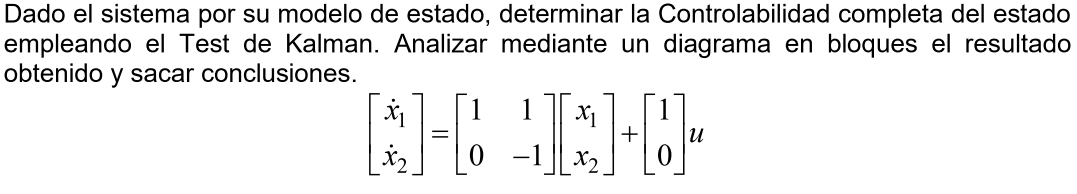

Primero obtenemos la matriz de controlabilidad


$$\begin{array}{l}
\left\lbrack C_o \right\rbrack =\left\lbrack \begin{array}{cc}
B & \textrm{AB}
\end{array}\right\rbrack \\
\left\lbrack C_o \right\rbrack =\left\lbrack \begin{array}{cc}
1 & 1\\
0 & 0
\end{array}\right\rbrack 
\end{array}$$


Calculamos el determinante de la matriz para saber si hay filas o columnas linealmente dependientes,


$$\begin{array}{l}
\textrm{det}\left(C_o \right)=\left(1*0-0*1\right)\\
\textrm{det}\left(C_o \right)=0\;
\end{array}$$


Por lo tanto, el sistema no es controlable.

En MATLab podemos hallar el rango de la matríz y verificar si es menor al número de columnas de la matriz,

A = [1, 1; 0, -1];
B = [1; 0];
Co=[B A*B];
Size = size(Co);
R = rank(Co);
if R >= (Size(2))
    disp('El sistema es Controlable');
else
    disp('El sistema no es Controlable');
end

El sistema no es Controlable


Diagrama en bloques,